# Discrimination vs. Detection: intermediate results

Full results from all subjects.

clc; clear all; close all;
data_struct = loadData();
subjects = data_struct.keys;

## Coherence levels for all participants.

The first graph is simply the coherence values for the two tasks as a function of time. The second graph is the coherence values for the two tasks within participant, as a trajectory in detectionXdiscrimination space - they all start from (1,1) and move downward and rightward as a function of their improvement. Apart from one outlier all participants converged to coherence values of around .3 for detection and .15 for discrimination.

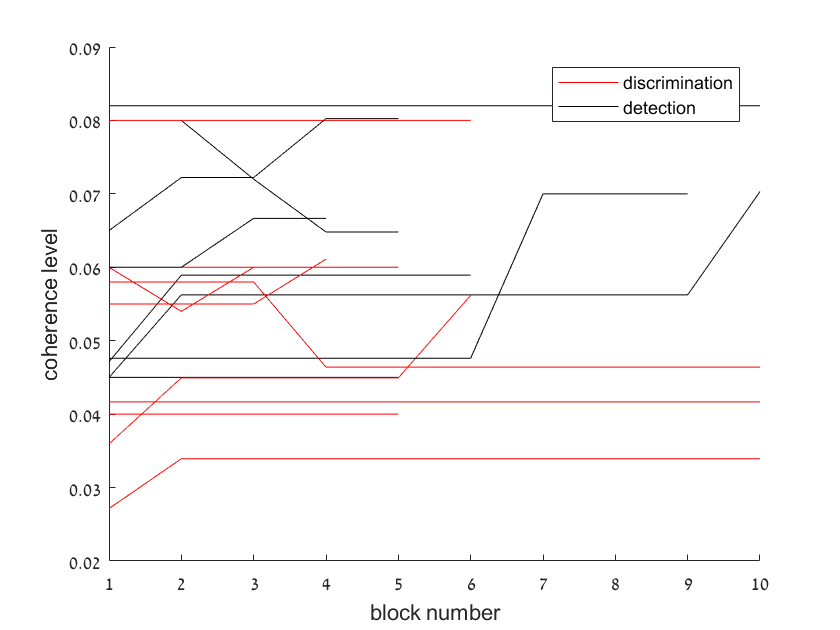

figure
hold on
for s=1:length(subjects)
    subject = data_struct(subjects{s});
    plot(subject.DisWg,'red');
    plot(subject.DetWg,'black');
    legend('discrimination', 'detection')
    xlabel('block number')
    ylabel('coherence level')
end

## zROC

To compare type-I and type-II sensitivity between tasks and responses I plot the zROC curve for each task and subject. 

Confidnece ratings are binned into 6 bins (12 possible responseXconfidnece pairs) at the subject level (and not at the task or at the response level). The bins are defined to have an equal number of trials overall, but they can have different number of trials within task or response.

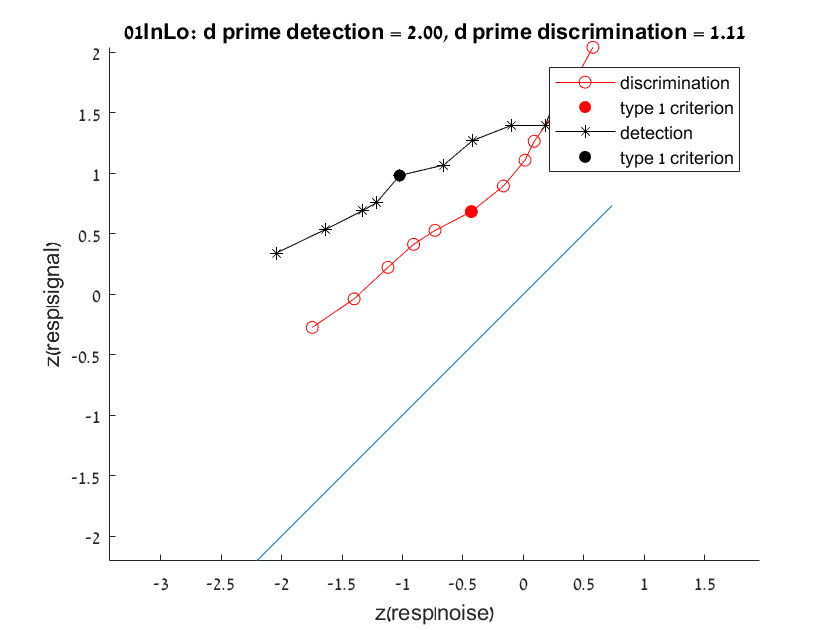

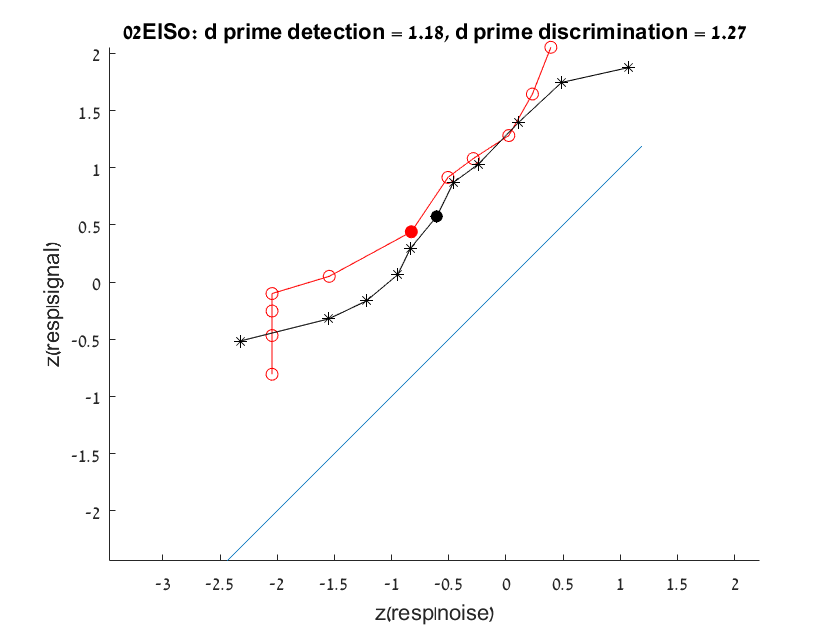

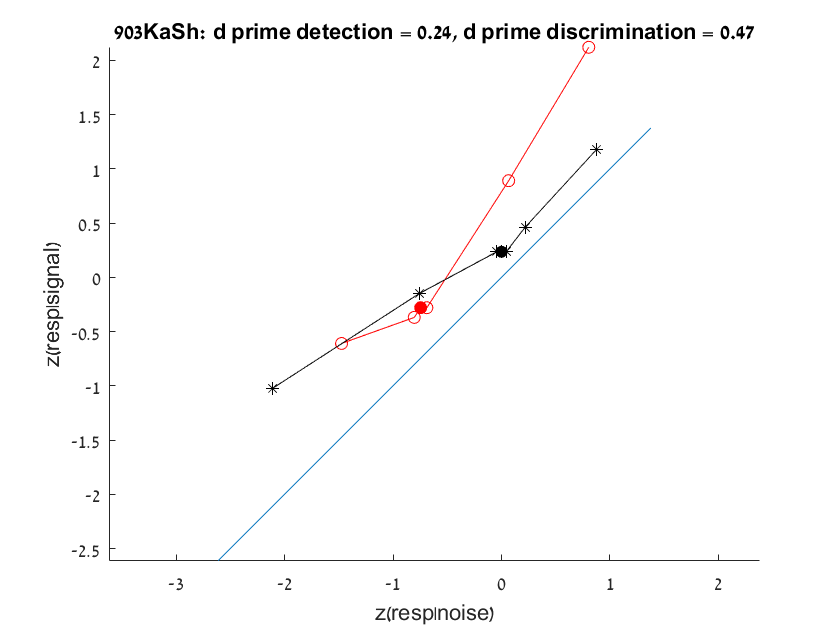

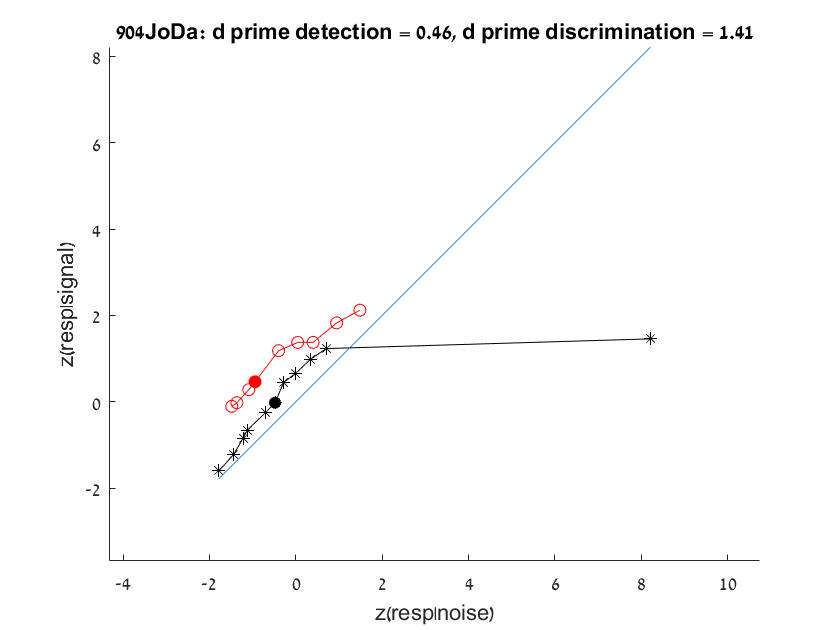

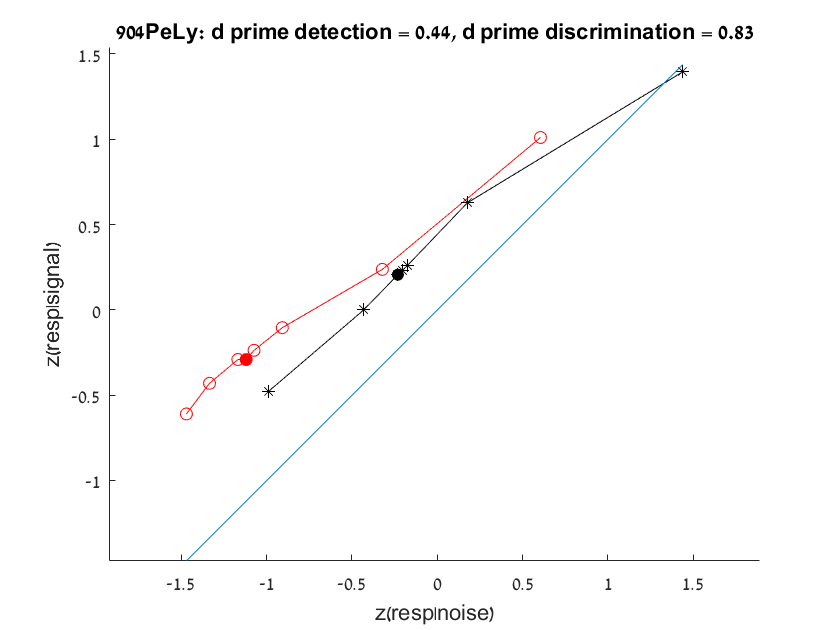

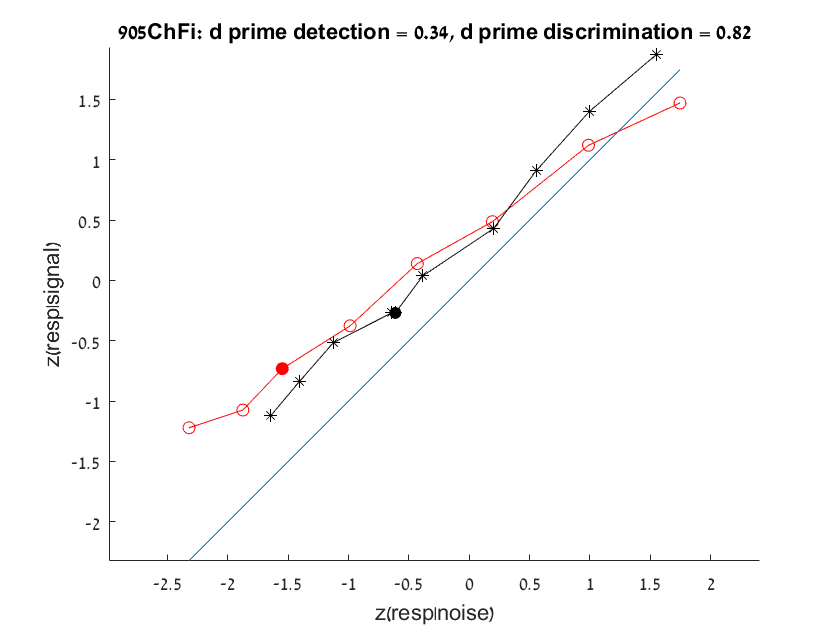

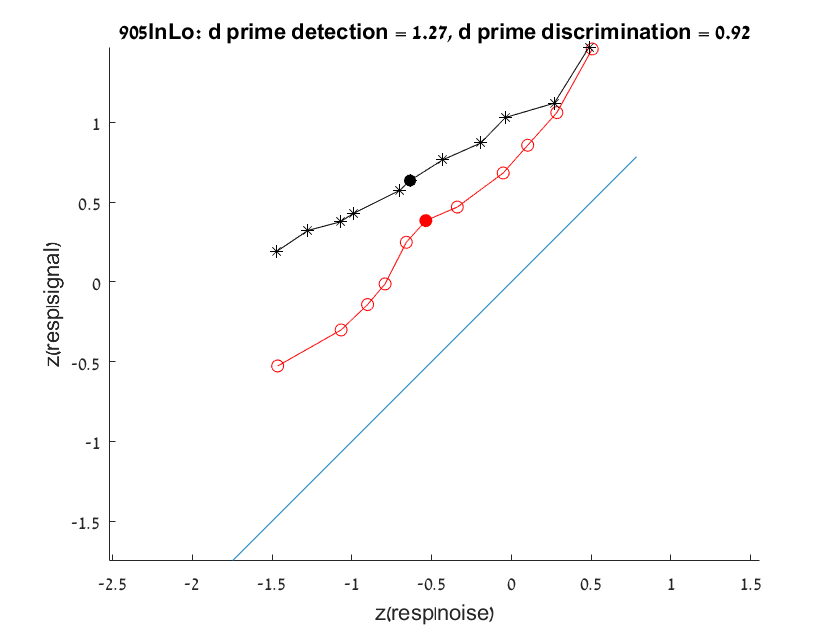

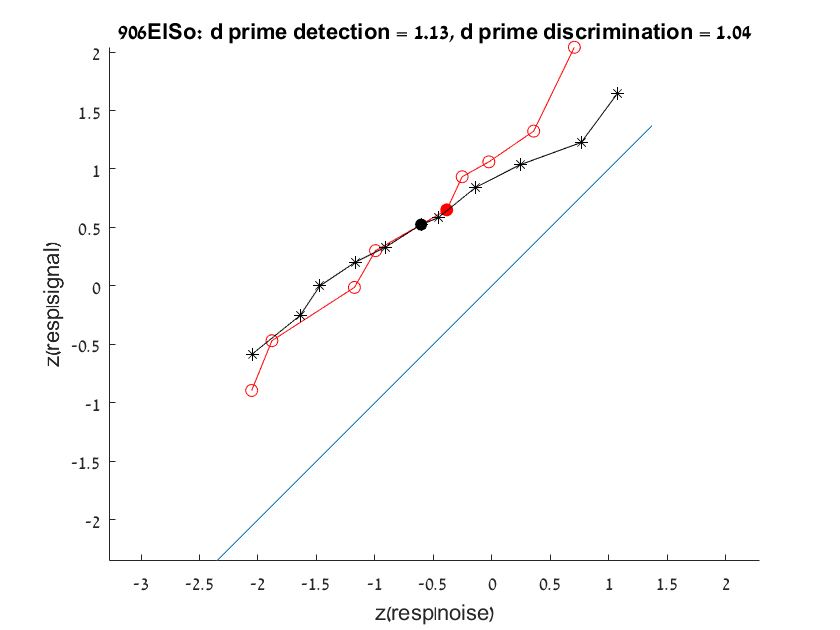

for s=1:length(subjects)
    
    subject = data_struct(subjects{s});
   
    DisConfResponses = 2*(subject.DisResp-0.5).*subject.DisConf;
    DetConfResponses = 2*(subject.DetResp-0.5).*subject.DetConf;

    %create response count vectors, compute response probabilities 
    % and extract corresponding Z values
     DetSignalResponseCount = histc(DetConfResponses(subject.DetSignal==1), -6:6);
%     DetSignalResponseCount = hist(DetConfResponses(subject.DetSignal==1), 1000);
    pDetSignal = DetSignalResponseCount/sum(DetSignalResponseCount);
    zDetSignal = norminv(cumsum(pDetSignal(end:-1:2)));
    
    DetNoiseResponseCount = histc(DetConfResponses(subject.DetSignal==0), -6:6);
%     DetNoiseResponseCount = hist(DetConfResponses(subject.DetSignal==0), 1000);
    pDetNoise = DetNoiseResponseCount/sum(DetNoiseResponseCount);
    zDetNoise = norminv(cumsum(pDetNoise(end:-1:2)));
    
    DisS1ResponseCount = histc(DisConfResponses(subject.DisSignal==1), -6:6);
%     DisS1ResponseCount = hist(DisConfResponses(subject.DisSignal==1), 1000);
    pDisS1 = DisS1ResponseCount/sum(DisS1ResponseCount);
    zDisS1 = norminv(cumsum(pDisS1(end:-1:2)));
    
    DisS2ResponseCount = histc(DisConfResponses(subject.DisSignal==0), -6:6);
%     DisS2ResponseCount = hist(DisConfResponses(subject.DisSignal==0), 1000);
    pDisS2 = DisS2ResponseCount/sum(DisS2ResponseCount);
    zDisS2 = norminv(cumsum(pDisS2(end:-1:2)));
    
    %plot
    figure;
    hold on;
    axis equal
    plot(zDisS2,zDisS1,'-or')
    scatter(zDisS2(6), zDisS1(6), 'red','filled')
    plot(zDetNoise, zDetSignal, '-*k')
    scatter(zDetNoise(6), zDetSignal(6),'black','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('%s: d prime detection = %.2f, d prime discrimination = %.2f', ...
        subjects{s}, zDetSignal(6)-zDetNoise(6), zDisS1(6)-zDisS2(6)));
    if s==1
        legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion')
    end

end

## Response conditional ROCs

Here I plot the response conditional ROCs for the two tasks.

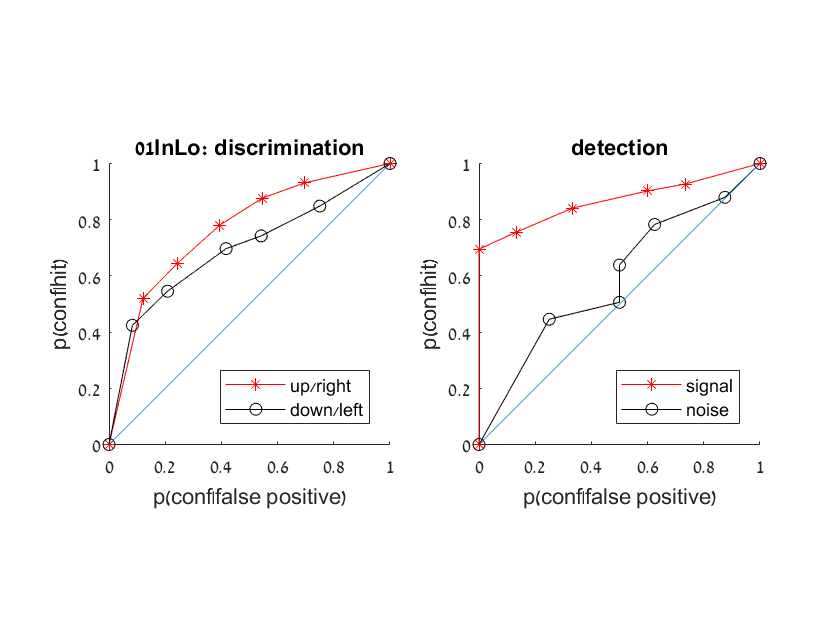

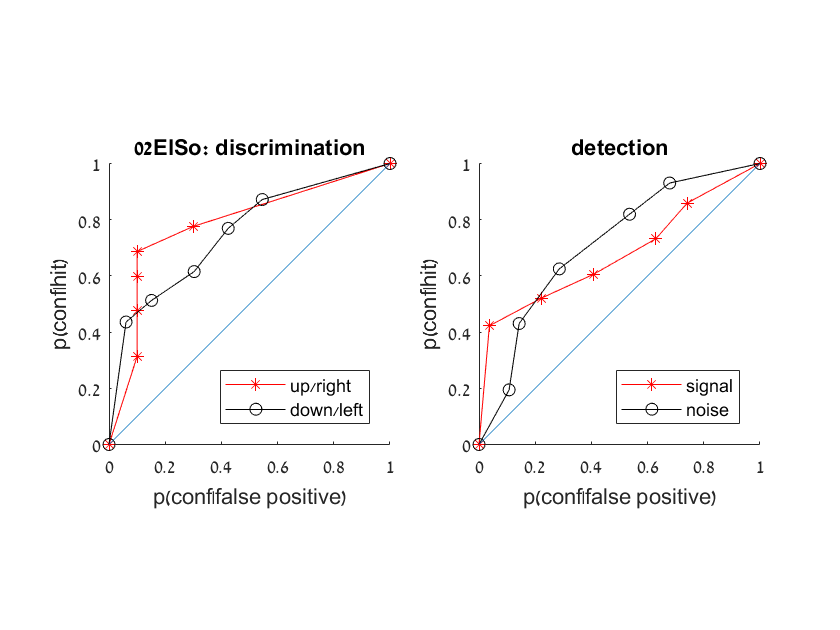

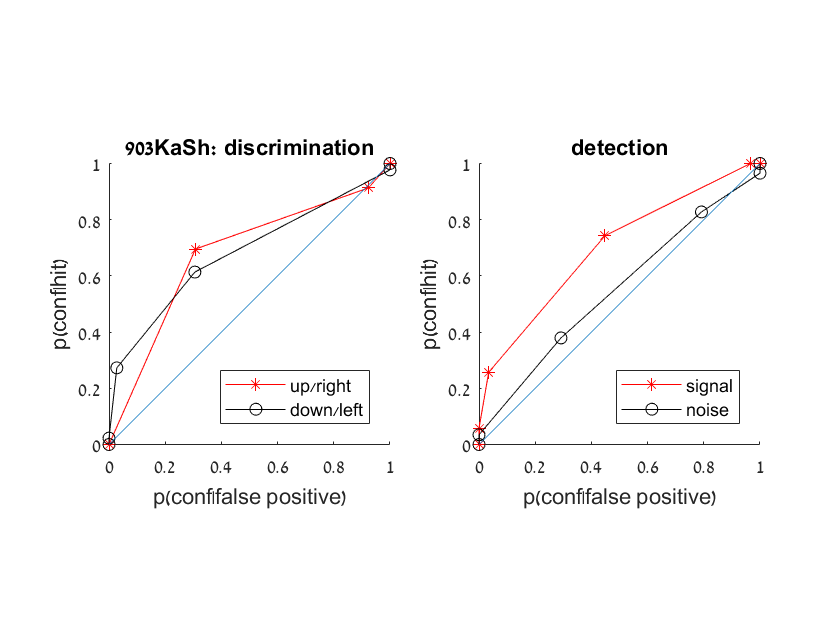

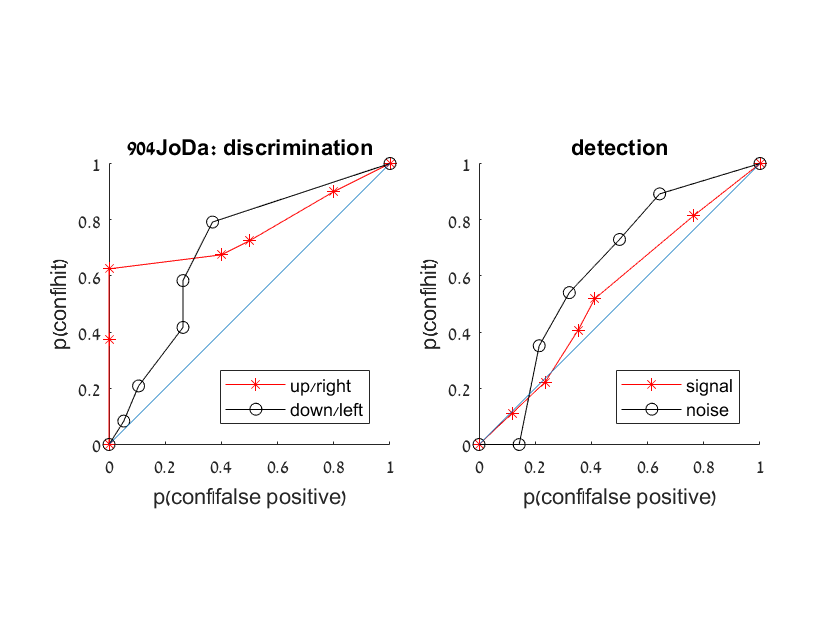

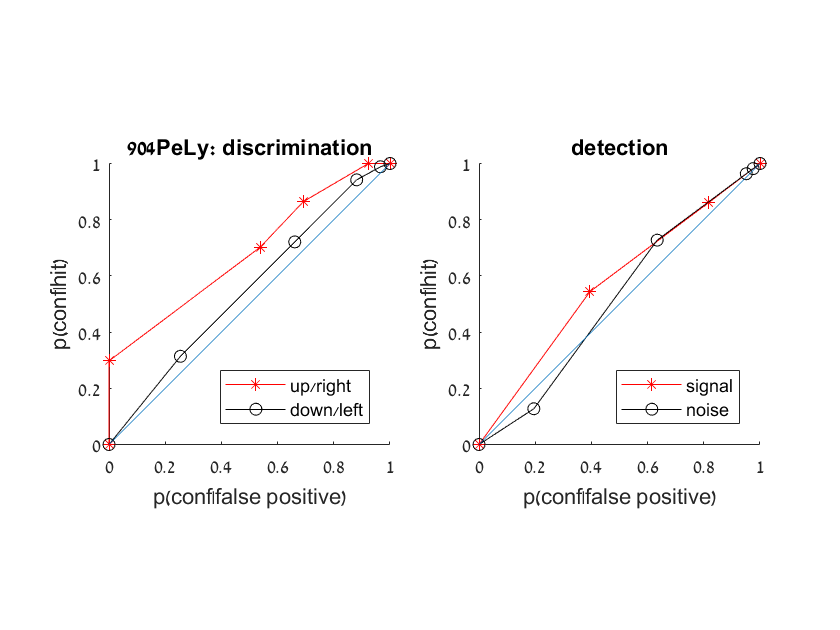

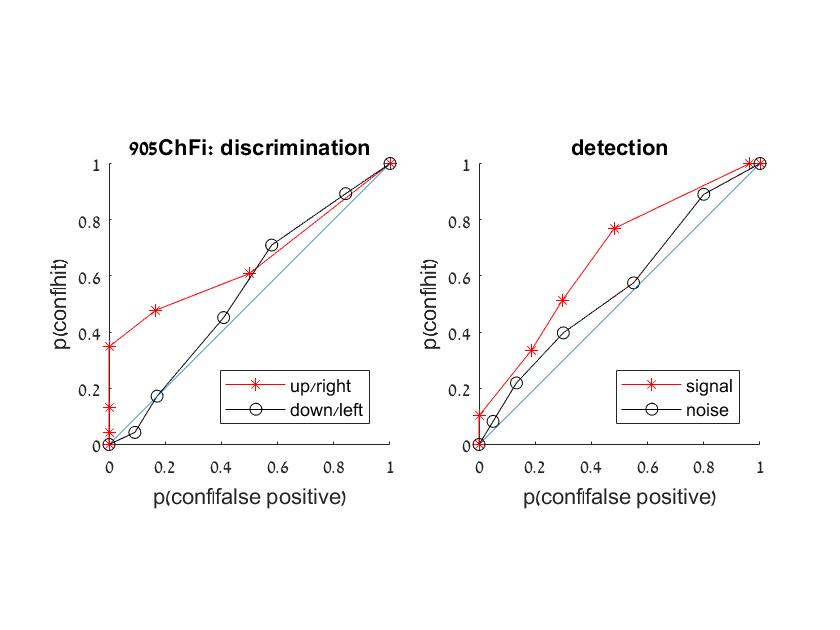

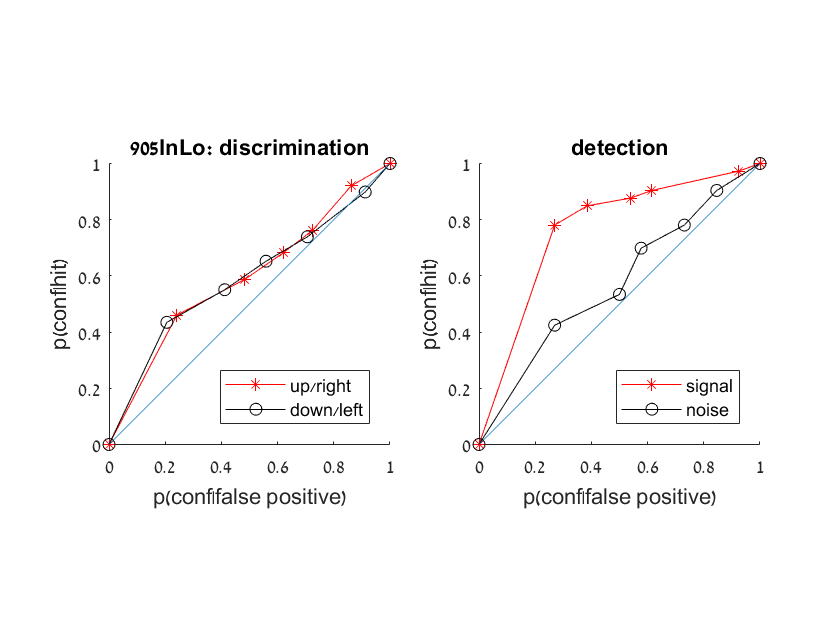

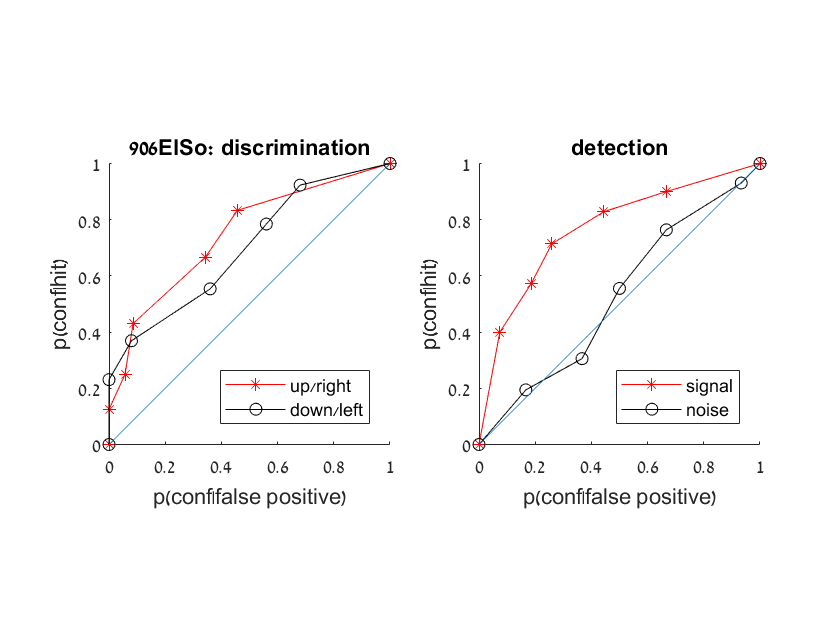

[DownUpGroup, UpUpGroup,UpDownGroup, DownDownGroup] = deal([]);
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);

for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);

    
    %break into taskXresponseXsignal
    DisUpUp = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1),1:6);
    DisUpDown = histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0),1:6);
    DisDownUp = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1),1:6);
    DisDownDown = histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0),1:6);
    DetSignalYes = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1),1:6);
    DetSignalNo = histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0),1:6);
    DetNoiseYes = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1),1:6);
    DetNoiseNo = histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0),1:6);
    

    %% plot discrimination
    figure;
    subplot(1,2,1);
    hold on;
    axis equal
    
    %up responses
    plot([0; cumsum(DisDownUp(end:-1:1))/sum(DisDownUp)],...
        [0; cumsum(DisUpUp(end:-1:1))/sum(DisUpUp)], '-*r');
    
    DownUpGroup = [DownUpGroup [0; cumsum(DisDownUp(end:-1:1))/sum(DisDownUp)]];
    UpUpGroup = [UpUpGroup [0; cumsum(DisUpUp(end:-1:1))/sum(DisUpUp)]];

    %down responses
    plot([0; cumsum(DisUpDown(end:-1:1))/sum(DisUpDown)],...
        [0; cumsum(DisDownDown(end:-1:1))/sum(DisDownDown)], '-ok');
    
    DownDownGroup = [DownDownGroup [0; cumsum(DisDownDown(end:-1:1))/sum(DisDownDown)]];
    UpDownGroup = [UpDownGroup [0; cumsum(DisUpDown(end:-1:1))/sum(DisUpDown)]];
    
    xlabel('p(conf|false positive)');
    ylabel('p(conf|hit)');
    title([subjects{s}, ': discrimination']);
    xticks(0:0.2:1); xlim([0,1]);
    yticks(0:0.2:1); ylim([0,1]);
    refline(1,0);
    legend('up/right', 'down/left', 'Location', 'southeast')
    
    %% plot detection
    subplot(1,2,2);
    hold on;
    axis equal
    
    %yes responses
    plot([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
        [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)], '-*r');
    
    NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
    SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
    
    %no responses
    plot([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
        [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)],'-ok');

    NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
    SignalNoGroup = [SignalNoGroup [0;
        cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
    
    xlabel('p(conf|false positive)');
    ylabel('p(conf|hit)');
    title('detection');
    xticks(0:0.2:1); xlim([0,1]);
    yticks(0:0.2:1); ylim([0,1]);
    refline(1,0);
    legend('signal', 'noise', 'Location', 'southeast')
    
end

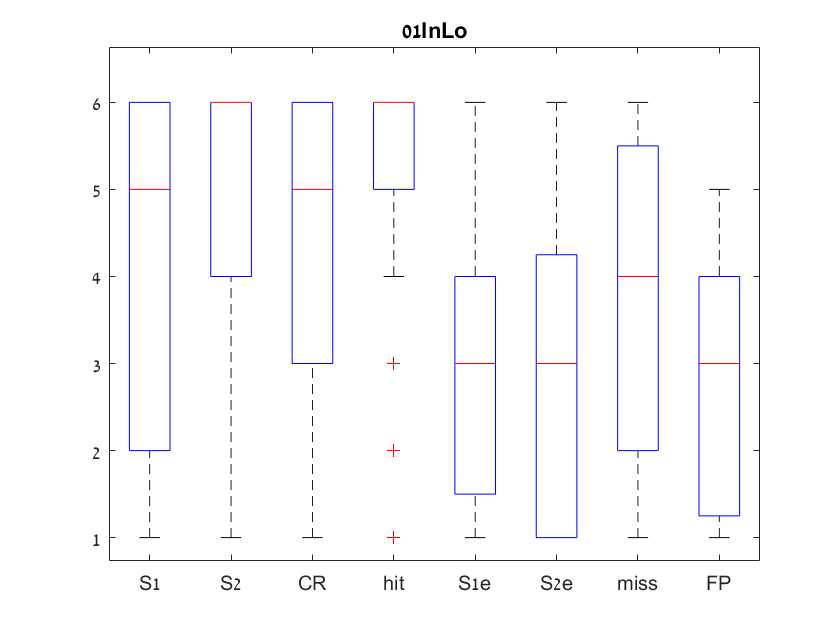

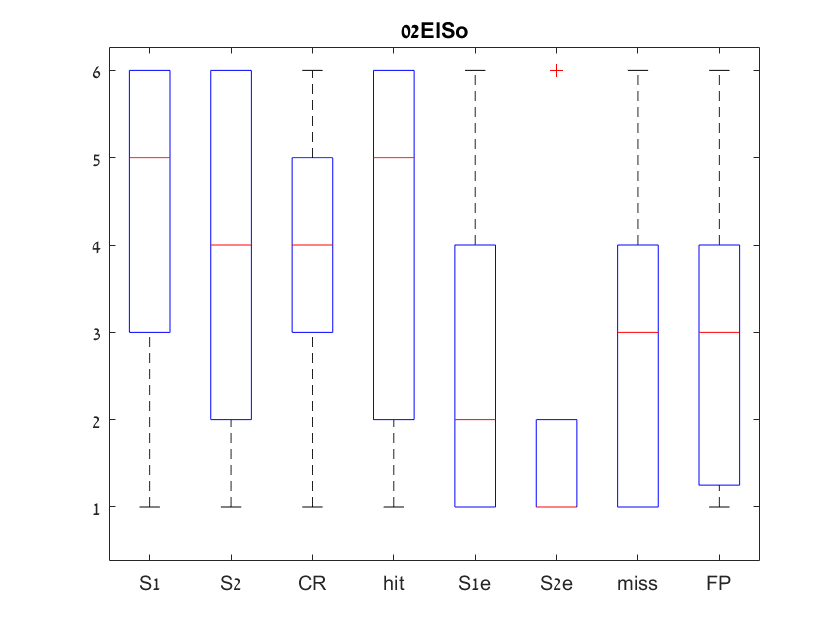

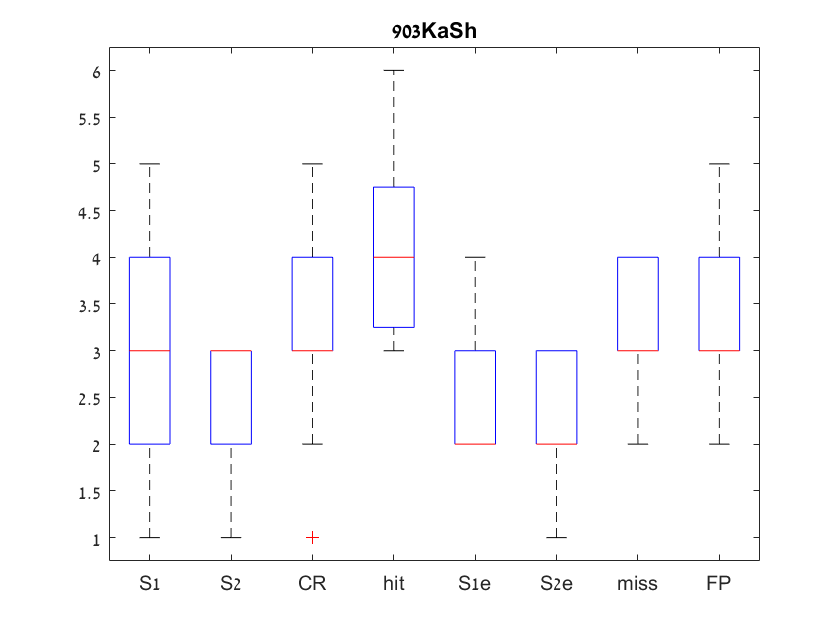

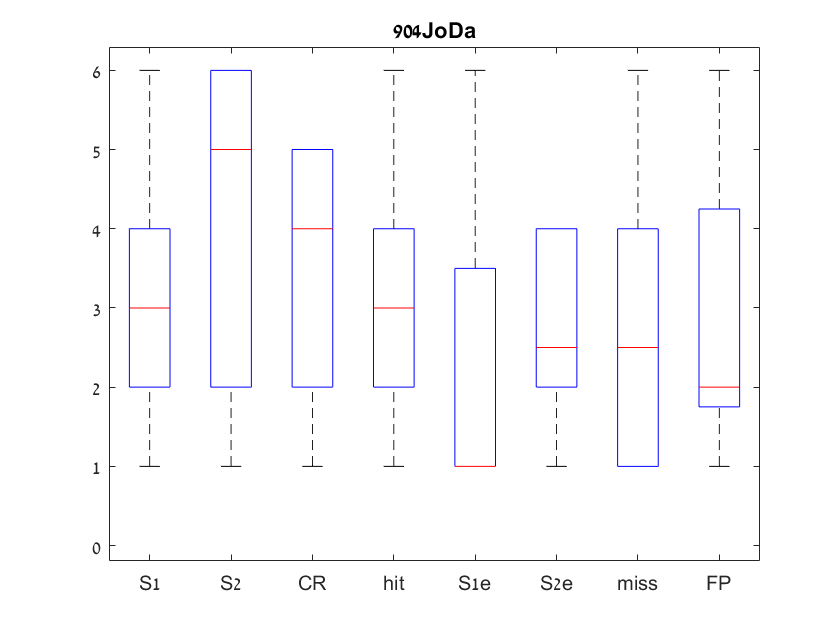

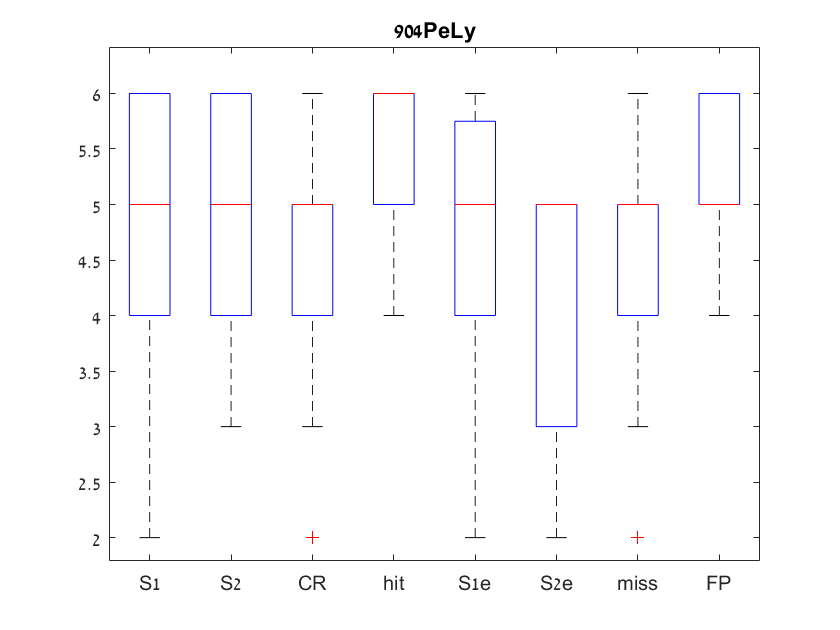

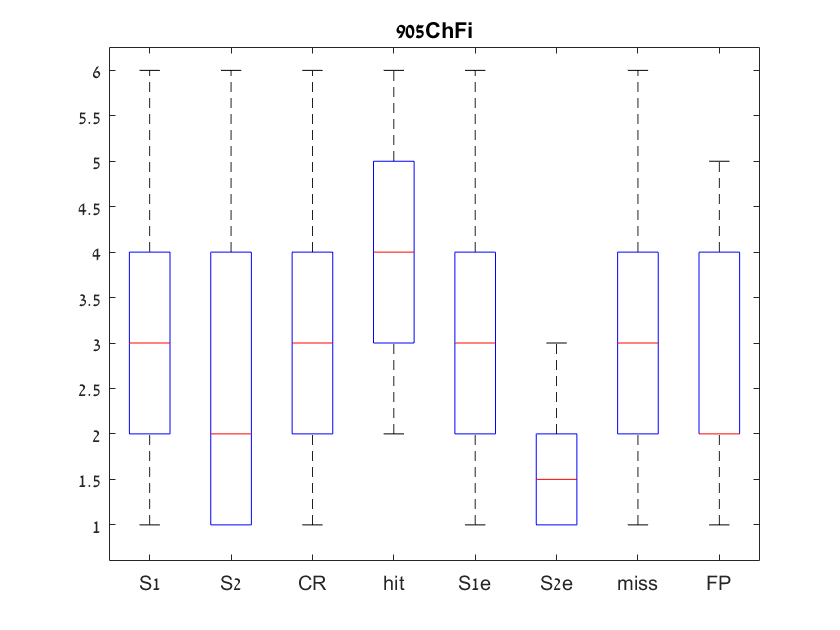

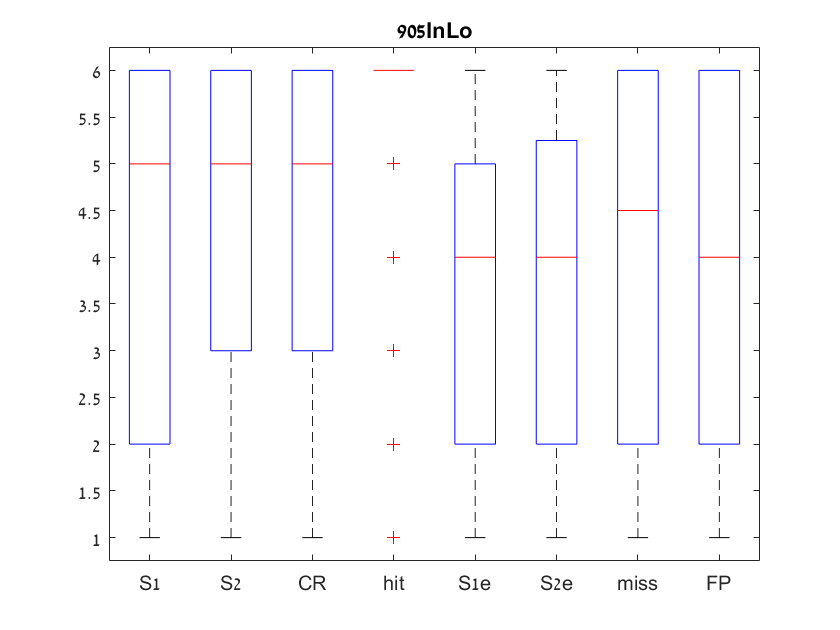

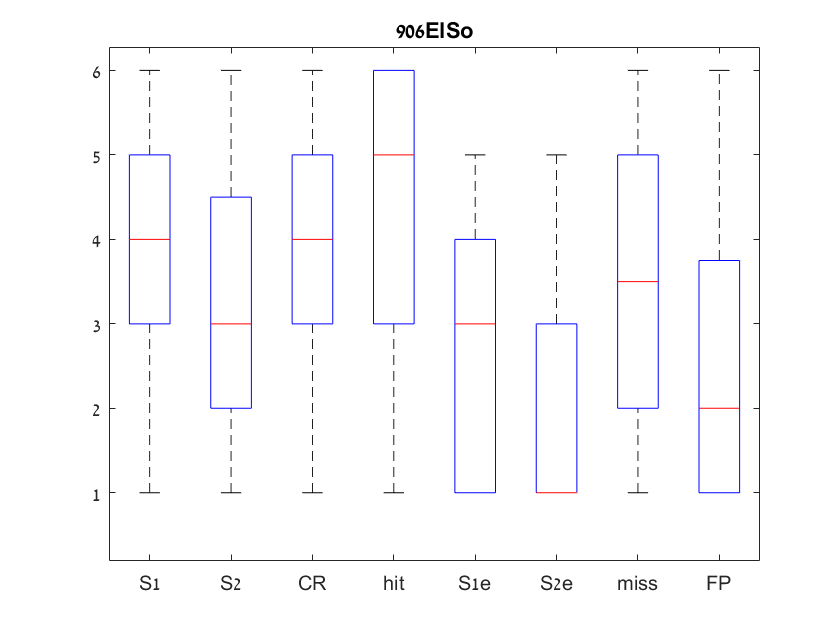

for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);
    figure;
    title(subjects{s})
    hold on
    boxplot([subject.DisConf(subject.DisCorrect==1); %%CORRECT RESPONSES
        subject.DetConf(subject.DetCorrect==1);...
        subject.DisConf(subject.DisCorrect==0); %%INCORRECT RESPONSES
        subject.DetConf(subject.DetCorrect==0)],...
        ...
        [subject.DisResp(subject.DisCorrect==1);...%%CORRECT RESPONSES
        2+subject.DetResp(subject.DetCorrect==1);...
        4+subject.DisResp(subject.DisCorrect==0);...%%INCORRECT RESPONSES
        6+subject.DetResp(subject.DetCorrect==0)], ...
        'Labels', {'S1','S2','CR','hit', 'S1e','S2e', 'miss', 'FP'})

end